# Nguyên tắc cơ bản của lập trình thực tế

[Menu menu chính](matlab:open('MainMenu.mlx'))

Lập trình liên quan đến việc sử dụng hiệu quả các tài nguyên tính toán để giải quyết các vấn đề. Một số vấn đề rất khó để xây dựng như một chương trình máy tính (ví dụ: "xe tự lái") trong khi những vấn đề khác khá đơn giản (ví dụ: "tính gần đúng nghiệm phương trình vi phân bậc nhất"). Những điều này không nhất thiết phải tương quan với khó khăn của một vấn đề theo cảm nhận của con người. Cân nhắc cố gắng "lập trình máy tính của bạn để xác định một bức ảnh của một con mèo" so với "chương trình máy tính của bạn để xác định đường bay tối ưu đến mặt trăng". Về cơ bản, các máy tính là một hiện tượng khi lặp lại và thực hiện các tính toán toán học, vì vậy đó là những tính năng chúng ta sẽ xem xét chủ yếu trong suốt cuộc thảo luận này về các nguyên tắc cơ bản của lập trình.

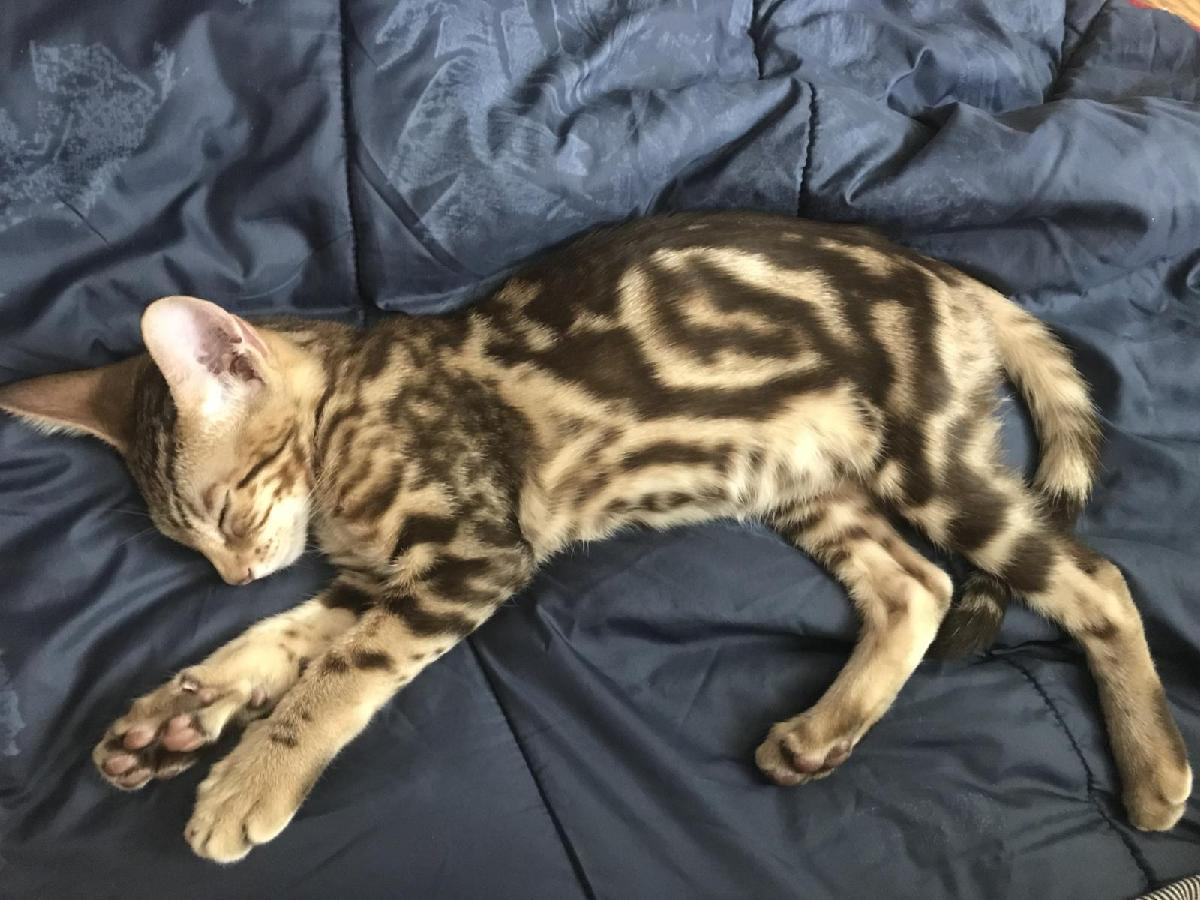                  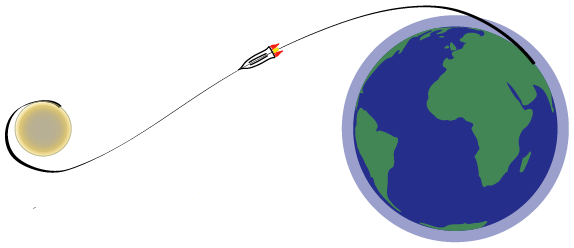

Mô -đun này sẽ cung cấp cho bạn các công cụ cơ bản cần thiết để giao tiếp với máy tính cách giải quyết vấn đề cho bạn.

**Trước khi bạn bắt đầu:**

Tập lệnh trực tiếp này được dự định sẽ được sử dụng với mã hiển thị và đầu ra nội tuyến. TRÊN menu **View tab** của công cụ MATLAB, trong Phần **View**, chọn **Output Inline**. Thay phiên, chọn **Output inline **Sử dụng biểu tượng Ở phía trên bên phải của Live Editor pane.

 Tương tác với kịch bản trực tiếp này sẽ xây dựng một số quen thuộc với MATLAB, vì các khái niệm và lệnh được giới thiệu cùng nhau. Nếu bạn cần thêm hướng dẫn, hãy xem xét việc thực hiện [Matlab Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), Một hướng dẫn trực tuyến 2 giờ miễn phí dạy các yếu tố cần thiết của MATLAB.

 Để có trải nghiệm tối ưu, hãy làm theo các hướng dẫn và các bước trong chuỗi đã cho. Chỉ tiến hành một phần mới sau khi hoàn thành phần trước, bao gồm chạy các khối mã trong đó.

## Các thành phần cơ bản để lập trình

### Lập trình là gì?

Lập trình máy tính có thể có nghĩa là một loạt các thứ khác nhau dựa trên ngữ cảnh, nhưng với mục đích của mô-đun này, chúng tôi sẽ định nghĩa lập trình máy tính là sử dụng ngôn ngữ được xác định trước để nói với máy tính để thực hiện các hoạt động cụ thể theo trình tự nhất định. Trong một số trường hợp, tất cả các hướng dẫn phải được cung cấp cùng một lúc và máy tính chỉ cần chuyển sang cái tiếp theo ngay khi nó đã xử lý các hướng dẫn trước đó. Trong các trường hợp khác, lập trình viên có thể tham gia tương tác hơn và thay đổi hướng dẫn của họ dựa trên các phản hồi trung gian của máy tính. Trong suốt mô -đun này, bạn sẽ tương tác với máy tính của mình theo cả hai cách này.

### Đầu vào đơn giản

Để lập trình một máy tính, bạn cần biết những thông tin bạn có sẵn để bắt đầu, chẳng hạn như dữ liệu, ví dụ: các ngày trong tuần. Chạy khối mã này bằng cách nhấp vào  **Run Section **nút trong **Live Editor** tab.

["Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday" "Sunday"]

Giá trị đầu vào là thông tin được cung cấp cho một chương trình trước khi tính toán và các giá trị đầu ra là thông tin được cung cấp bởi một chương trình sau khi tính toán.

 **Phản ánh**

- Bạn nhận thấy gì về đầu ra khi bạn chạy mã này? Các dấu ngoặc vuông có trong đầu ra không? Còn dấu ngoặc kép thì sao? Có văn bản bổ sung nào trong đầu ra không? Điều này đặt ra câu hỏi gì?

- Đầu vào của chương trình này là gì? Tại sao đầu vào trong dấu ngoặc vuông? Các khoảng trắng có quan trọng không? Còn dấu ngoặc kép thì sao?

Mã này tạo ra một tập hợp các giá trị được nhóm. Các cấu trúc liên quan đến ghi chú ghi chú tập hợp này là một`Chuỗi 1x7`s ẽ được thảo luận trong [`Data`](matlab:open('./Data.mlx')) live script. Hiện tại, hãy xem xét chi tiết biến `ans = `

Cụm từ `ans `là viết tắt của `answer`. Gõ  `ans vào t`rong khối mã bên dưới và sau đó chạy phần này. Bạn mong đợi điều gì?

Tuy nhiên, nên sử dụng các tên mô tả và duy nhất để định nghĩa các dữ liệu. Chạy phần code mới này. Điều gì đã thay đổi trong output ?

DaysOfWeek = ["Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday" "Sunday"]

### Lỗi

Điều gì xảy ra nếu bạn chạy mã bên dưới mà không có dấu ngoặc kép?

DaysOfWeek = [Monday Tuesday Wednesday Thursday Friday Saturday Sunday]

Mã này tạo ra một *lỗi*. Các ngôn ngữ lập trình khác nhau cảnh báo về các lỗi theo những cách khác nhau, nhưng có một số điểm tương đồng. Một tiêu chuẩn là mã lỗi và/hoặc thông báo lỗi. Nếu đây là lần đầu tiên bạn nhìn thấy một thông báo lỗi, thì cũng đừng sợ. Nó ở đây để giúp bạn sửa code của bạn. Mỗi lập trình viên, ngay cả những người chuyên nghiệp và có kinh nghiệm nhất, đôi khi viết mã với lỗi. Trong một kịch bản trực tiếp như thế này có một 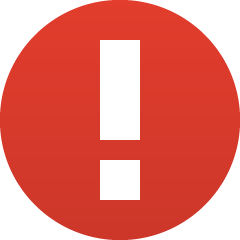 Biểu tượng ở phía trên bên trái của cửa sổ cũng như ở phía bên phải của dòng nơi đặt lỗi ngoài văn bản màu đỏ đánh vần thông báo lỗi. Trong trường hợp này, không có dấu ngoặc kép, Matlab đang diễn giải `Monday `Là một lệnh lập trình mà nó không nhận ra thay vì là dữ liệu.

Khi bạn gặp lỗi, hãy đọc các thông báo lỗi và tìm ra nơi lỗi đang được tạo. Thông thường, điều này sẽ cho phép bạn sửa lỗi và tiếp tục với chương trình của bạn. Trong trường hợp này, hãy thử thêm dấu ngoặc kép xung quanh tất cả các từ bên trong dấu ngoặc như vậy:

trong Khối mã trong dòng 4. Điều gì xảy ra khi bạn chạy mã này? Cái gì giống nhau? Có gì khác nhau?

 **Cảnh báo:**Bạn phải sửa bất kỳ lỗi nào trong mã trước khi bạn có thể chạy bất kỳ mã nào phụ thuộc vào nó. Trong trường hợp này, mỗi phần được xử lý độc lập, nhưng nếu bạn cố gắng chạy tất cả mã trong toàn bộ tập lệnh cùng một lúc bằng cách nhấp vào  nút **Run **trong **Live Editor** tab, không có mã nào qua phần này sẽ chạy cho đến khi bạn sửa lỗi.

  **Pro-tip**. Nếu bạn vô tình chạy mã, bạn không có ý định chạy, bạn có thể xóa tất cả đầu ra trong toàn bộ tệp bằng cách nhấp vào  **Clear all Output **nút trong **View** tab hoặc nhấp chuột phải để hiển thị menu ngữ cảnh trên một khối mã cụ thể và chọn **Clear Output** Để chỉ xóa đầu ra trong phần đó.

Tuy nhiên, không phải mọi loại dữ liệu đều yêu cầu dấu ngoặc kép được lưu trữ đúng cách. Chạy khối mã bên dưới:

% How many turkeys did I see each day last week?
NumTurkeys = [9 6 8 5 7 9 8]

  **Thử**

- Xóa comment

            và chạy lại mã. Những thay đổi nào?

        2. Thêm dấu chấm phẩy vào cuối dòng mã như vậy:

            Điều gì xảy ra khi bạn chạy mã bây giờ?

        3. Chỉnh sửa giá trị tương ứng với ngày thứ ba trong tuần. Có lẽ bạn đã thấy 0 con gà tây vào thứ Tư? Sau đó chạy lại mã. Những thay đổi nào? Bạn có thể nói? Hãy thử nhìn vào cửa sổ không gian làm việc.

 **Phản ánh**

- Nhận xét nên được sử dụng như thế nào?

- Bạn có thể nghĩ về các tình huống mà bạn có thể muốn chạy mã, nhưng triệt tiêu đầu ra?

### Comments

Mỗi ngôn ngữ lập trình đều có cách đánh dấu các phần của mã là *comments*. Các phần *comments* bị bỏ qua hoàn toàn bởi máy tính khi nó chạy qua phần còn lại của chương trình. Comments nên được sử dụng để cung cấp thông tin cho người đọc một chương trình theo cách thêm giá trị. Matlab sử dụng một % để đánh dấu phần còn lại của dòng đó là một bình luận. Python sử dụng # , trong khi C, Comments là bất kỳ số lượng văn bản nào giữa / * và * /.

  **Pro-tip**. Ngôn ngữ lập trình cần một cách để truyền đạt kết quả cho các lập trình viên. Phiên bản đơn giản nhất của điều này thường được gọi là "standard output" và thường bao gồm in kết quả trên màn hình. Thêm một dấu chấm phẩy ở cuối dòng trong Matlab cho máy tính nói với máy tính rằng bạn không muốn hiển thị kết quả của dòng đó dưới dạng đầu ra tiêu chuẩn. Ngôn ngữ lập trình cũng phải lưu trữ nhiều hơn một bit dữ liệu cùng một lúc. Một số ngôn ngữ lập trình chia sẻ thông tin về những gì hiện đang được lưu trữ và do đó có sẵn để truy cập. MATLAB cung cấp thông tin này trong cửa sổ không gian làm việc bên phải. Những dữ liệu nào có sẵn cho bạn vào lúc này?

Cũng có thể cung cấp dữ liệu tương tác với máy tính. Hãy thử di chuyển thanh trượt này qua lại. Chọn một giá trị mới cho`Wedturkeys`Sẽ chạy tất cả các mã trong phần này của tập lệnh.

WedturKeys = 4.5;
NUMTURKEYS = [9 6 WedTurkeys 5 7 9 8]

Tất cả thông tin bên ngoài nhập một chương trình máy tính có thể được xem xét đầu vào. Mức đầu vào là nơi các cảm biến và tính tương tác của người dùng, ví dụ, có thể cung cấp thông tin cho hệ thống.

  **Thử**. Bạn có thể chạy phần mã này như bình thường, mà chỉ cần di chuyển thanh trượt để đặt giá trị dương của `WedTurkeys `Cũng sẽ kích hoạt phần để chạy.

- Thay đổi giá trị của `WedTurkeys `với giá trị ban đầu là 8. Điều gì xảy ra với `NumTurkeys ?`

- Thay đổi giá trị của `WedTurkeys `đến 3,5. Những gì xảy ra với `NumTurkeys`? Có nhiều cuộc thảo luận về việc lưu trữ các số trong mã trong [Data.mlx](matlab:open('./Data.mlx')).

- Nhìn vào các biến trong Workspace. Điều gì đã xảy ra với   `NumTurkeys ban đầu?`

- Thêm một nhận xét cho khối mã này giải thích những gì nó làm.

 **Phản ánh**

- Bạn nhận thấy gì về kết quả khi bạn chạy mã này? Điều này đặt ra câu hỏi gì?

- Chương trình có tạo ra lỗi nếu số lượng của bạn liên quan đến gà tây một phần không? Tại sao hoặc tại sao không?

- Bạn có thể cho biết ranh giới section ở đâu? Tại sao hoặc tại sao không?

  **Pro-tip**. Lưu ý rằng mã có số dòng được liên kết với nó. Các   **Run** command chạy từng dòng mã theo thứ tự từ dòng 1 cho đến dòng cuối cùng trong tập lệnh. Bạn có thể xóa đầu ra trong tập lệnh trong **View** tab bằng cách nhấp vào **Clear all Output**.

Bạn đã thấy các cách để nhập cả dữ liệu văn bản và dữ liệu số, nhưng máy tính có thể xử lý nhiều loại dữ liệu khác cũng như hình ảnh, video hoặc tệp âm thanh. Bạn nghĩ điều gì sẽ xảy ra khi bạn chạy mã bên dưới?

% Tải một hình ảnh của gà tây
PicturKeys = imread("turkeys1.jpg")

Máy tính của bạn chỉ cho bạn thấy cách nó thực sự hiểu tệp hình ảnh này. Bạn có thể điều tra điều này thêm trong [Arrays.mlx](matlab:open('./Arrays.mlx')). Đây là một ví dụ tốt về một dòng mã dễ xử lý hơn nhiều nếu bạn triệt tiêu đầu ra bằng cách thêm dấu chấm phẩy.

## Lệnh

Bạn cũng cần nói với máy tính phải làm gì với đầu vào. Để lấy cảm hứng, hãy xem xét máy tính đơn giản được gọi là máy tính:

4+7
35/65
-2*3.2
sin(pi/2)

Lưu ý rằng ba lần đầu tiên là các tính toán số học, nhưng cái cuối cùng là một hàm có một số trong radian và tính toán sin.  Lệnh cuối cùng, `sin(pi/2)`, có lẽ có vẻ rất giống với ba bài toán số học đầu tiên. Tất cả chỉ là toán học! Tuy nhiên, nếu bạn cân nhắc một lúc, trong khi bạn biết cách tính toán `4+7 `hoặc`- 2*3.2 `hoặc thậm chí `35/65 `Nếu bạn phải làm, có lẽ bạn không biết cách tính toán $\sin(\theta)$ cho một giá trị tổng quát của $\theta$. Trên thực tế, nó là một tính toán liên quan nhiều hơn đáng kể với nhiều cộng, trừ, nhân và chia và vẫn sẽ chỉ cung cấp cho bạn một giá trị gần đúng. Mỗi hàm trong ngôn ngữ lập trình là một tên cho một tập hợp các hướng dẫn cụ thể mà máy tính sẽ tuân theo.

Có rất nhiều hàm có các loại đầu vào khác nhau. Chẳng hạn, có các chức năng sẽ lấy số lượng `picTurkeys `và hiển thị hình ảnh gà tây ở định dạng có thể đọc được hơn. Thử sử dụng lệnh`imshow:`

imshow(PicTurkeys)

 **Phản ánh**

- Điều này trông giống như gà tây đối với bạn hơn là code lúc trước?

- Những loại chức năng toán học khác mà bạn có thể mong đợi có trong một ngôn ngữ lập trình?

- Những loại chức năng khác mà bạn có thể muốn áp dụng cho một hình ảnh?

### Học thêm: Tài liệu

Bạn biết rằng đối số với hàm  `sin `Có thể là một số radian hoặc một số độ. Kết quả sẽ khác nhau trong mỗi trường hợp. Máy tính có một cài đặt cho biết thiết bị có nên giải thích đối số là ở radian hay bằng cấp. Có thể bạn đã gặp rắc rối với điều này trong quá khứ khi di chuyển giữa một lớp kỹ thuật hoặc vật lý và một lớp toán học. Trong Matlab, hàm `sin l`uôn luôn lấy tham số đầu vào là radian. Bạn có thể học điều đó, và nhiều hơn nữa, bằng cách đọc tài liệu về chức năng:

doc sin

  **Pro-tip**

Mặc dù nó có thể không giống như một fucntion, `doc sin `là một cách khác để đưa ra hướng dẫn cho máy tính. Cấu trúc này được gọi là Cú pháp lệnh trong MATLAB.

**Bài tập 1**

Khi đọc trang tài liệu cho `sin`, có một phần gọi là "See Also".

a. Hàm MATLAB sẽ tính toán sin của một đối số theo độ là gì?

b. Tên của hàm `sinh`?

c. Làm thế nào bạn sẽ tính toán$\ sin^{-1} (1/2)$ Trong radian? tính bằng độ?

Tên có thể mơ hồ. Nếu bạn được hỏi, "Bạn đã bao giờ đến Victoria chưa?" Bạn nghĩ về phần nào của thế giới? Có lẽ bạn xem xét Nhà nước Úc và có lẽ bạn xem xét thành phố ở British Columbia, Canada hoặc thậm chí là Thác Victoria trên sông Zambezi ở Châu Phi. Tên chức năng trong một chương trình không khác nhau, và nó có thể cần nghiên cứu cẩn thận để xác định sự khác biệt. Trong một số trường hợp, số lượng đầu vào hoặc đầu ra sẽ là chữ ký nhận dạng, trong khi ở những người khác, bối cảnh để sử dụng có thể khác nhau. Các tài liệu cho `imshow `chỉ ra nhiều đối số tiềm năng khác nhau trong khi tìm kiếm tài liệu`số phức`định vị một loạt các trang khác nhau trong tài liệu với một số chức năng và một số thông tin chung.

doc imshow
doc complex numbers

#### **Tổ chức tập tin**

Khi bạn thực hiện nhiều tìm kiếm tài liệu, mỗi kết quả sẽ mở trong tab của riêng họ trong cửa sổ trợ giúp với thuật ngữ tìm kiếm được sử dụng làm nhãn trên mỗi tab.

Các tệp được tổ chức thành các thư mục lồng nhau, cho đến gốc của hệ thống tệp, trong trường hợp này là "tài liệu". Khi kết quả là tìm kiếm, mỗi trận đấu cũng hiển thị đường dẫn tệp đến kết quả, chẳng hạn như:

Documentation > MATLAB > Mathematics > Elementary Math

Điều này cho thấy thư mục tài liệu gốc chứa thư mục MATLAB chứa thư mục Mathematics chứa thư mục Elementary Math có chứa, trong số các tệp khác, các số phức (Complex Numbers). Thông tin này có thể được sử dụng để điều hướng và cũng để giúp bạn chọn kết quả tìm kiếm nào phù hợp nhất với những gì bạn đang tìm kiếm.

**Bài tập 2**

a. Xác định một chủ đề khác ngoài "số phức" trong thư mục Elementary Math.

b. Xác định một chủ đề khác ngoài "Mathematics" trong thư mục MATLAB.

  **Pro-tip**. Bạn có thể thường xuyên tìm hiểu cú pháp lệnh cho một thao tác cụ thể trong một ngôn ngữ máy tính cụ thể bằng cách xem qua tài liệu của nó:

doc square root

  **Thử**. Hãy thử một số tính toán của riêng bạn bằng cách nhập biểu thức số học trong khối mã bên dưới và sau đó chạy phần này. Để giúp bạn bắt đầu, bạn có thể thể hiện hai giải pháp cho phương trình:


$$AX^2+BX+C = 0$$


- Với $a = -3$ và $B = 2$ Và$c = 6$

- Với $a = 2$ và $B = 17$Và$c = -70$

% Thể hiện các giải pháp cho AX^2 + BX + C = 0 bằng cách sử dụng bậc hai 
% công thức để tính toán root1 và root2 theo a, b và c

 **Lỗi phổ biến.**

- Mỗi dòng mã phải được hoàn thành và có thể hiểu được. Điều này có nghĩa là, ví dụ rằng bạn không thể kết thúc một dòng mã với + hoặc trước khi đóng một tập hợp các dấu ngoặc đơn.

- Viết hoa và vấn đề dấu câu. Chẳng hạn, các biến được đặt tên a và A là khác nhau.

- Tất cả các phép toán phải được nhóm rõ ràng và tường minh. Bạn có thể đã quen viết `+ v`à `- v`à `/ k`hi bạn cần cộng, trừ hoạc chia. Bạn có thể không quen viết `4*a*c` hơn là $4ac$. Tương tự, các ngôn ngữ lập trình tuân theo các quy tắc như làm việc ưu tiên thông qua "dấu ngoặc đơn, số mũ, phép nhân & chia, cộng & trừ" theo thứ tự từ trái sang phải để đánh giá các biểu thức toán học. Do đó `b/2*a `$= \left(\frac{b}{2}\right)\cdot a = \frac{ba}{2} \neq \frac{b}{2a} =$ `b/(2*a)`.

 **Phản ánh**

- Kết quả có phù hợp với kỳ vọng của bạn không?

- Có bất kỳ tính toán nào mà bạn muốn đánh giá, nhưng bạn không biết cách thể hiện?

Máy tính đại diện cho dữ liệu là 0 và 1, nhưng đó không phải là cách con người xử lý thông tin. Ngôn ngữ lập trình cung cấp một giao diện cho con người để nói với máy tính phải làm gì.  Khi bạn biết cú pháp của ngôn ngữ, bạn có thể đọc và ghi mã theo cách mà máy tính có thể hiểu và chuyển thành 0s và 1s. Một ngôn ngữ lập trình cấp thấp nhằm mục đích gần gũi hơn với cách máy tính hoạt động với các lệnh phù hợp với các hoạt động phần cứng. Điều này có thể quan trọng để tạo mã rất hiệu quả sẽ chạy nhanh chóng. Một ngôn ngữ lập trình cấp cao nhằm mục đích gần gũi hơn với cách con người nghĩ với các lệnh phù hợp với các cấu trúc và lệnh có thể đọc được của con người. Điều này đòi hỏi nhiều công việc hơn về một phần ngôn ngữ lập trình để dịch từ các hướng dẫn của con người sang các hoạt động mà máy tính có thể làm theo, nhưng điều này cũng có thể giúp bạn bắt đầu tạo mã hữu ích hơn vì nhiều hoạt động được xác định trước cho bạn. Mô-đun này sẽ tập trung vào việc học cách sử dụng ngôn ngữ lập trình cấp cao.

Đầu tiên, bạn cần hiểu điều gì đó về dữ liệu [đơn giản](matlab:open('./Data.mlx')) hoặc dữ liệu [cấu trúc](matlab:open('./Arrays.mlx')). Sau đó bạn cần có khả năng hướng dẫn một máy tính [đưa ra lựa chọn](matlab:open('./Branches.mlx')) hoặc [Lặp lại một hoạt động](matlab:open('./Loops.mlx')). Với những công cụ này, bạn sẽ có thể làm việc thông qua một số lớn hơn và hy vọng giải quyết vấn đề hấp dẫn hơn qua [dự án](matlab:open('./ChaosGameProject.mlx')) Và [Bài tập](matlab:open('./Algorithms.mlx'))

## Xây dựng các lệnh tổng hợp

Mặc dù các ngôn ngữ khác nhau nhằm mục đích làm cho các hoạt động khác nhau đặc biệt tự nhiên hoặc hiệu quả, mọi ngôn ngữ máy tính cũng bao gồm khả năng xác định và đặt tên cho các hoạt động của riêng bạn. Bạn có thể xây dựng các hoạt động mới này bằng cách kết hợp các hoạt động được xác định trước theo một cách mới. Xác định cách chia một vấn đề thành các mảnh nhỏ hơn hoặc đơn giản hơn mà bạn có thể giải quyết được gọi là *tư duy tính toán*. Tư duy tính toán này là kỹ năng có thể áp dụng rộng rãi nhất liên quan đến lập trình máy tính khi bạn học cách phân tách một hoạt động phức tạp thành các hoạt động thành phần đơn giản. Mô -đun chương trình giảng dạy này sẽ đưa bạn qua các khối xây dựng cơ bản cần thiết để bắt đầu viết các chương trình để giải quyết các câu hỏi quan tâm trong cuộc sống của chính bạn. Các [Dự án trò chơi hỗn loạn](matlab:open('./ChaosGameProject.mlx')) Tuy nhiên, dự định sẽ giới thiệu cách kết hợp một vài lệnh có thể dẫn đến kết quả rất phức tạp. Các ví dụ và bài tập trong [Thuật toán.MLX](matlab:open('./Algorithms.mlx')) sẽ cho phép bạn khám phá một vài loại mã hóa đơn giản cho cả văn bản và hình ảnh.

## Thận trọng

Khi chúng tôi đã chạm vào một thời gian ngắn, các máy tính sẽ làm chính xác những gì bạn bảo họ làm những gì có thể hoặc không phải là những gì bạn mong đợi hoặc dự định. Hãy xem xét thực tế là trong nhiều ngôn ngữ lập trình, có thể rất đơn giản để thay đổi dữ liệu được đính kèm với một tên hoặc quy tắc được đính kèm với một hàm mà không có bất kỳ cảnh báo nào mà bạn đã xác định lại một cái gì đó. Điều này thậm chí có thể áp dụng cho các giá trị tích hợp tiêu chuẩn bên trong ngôn ngữ như gõ

% Trình diễn về sự nguy hiểm của việc vô tình đặt lại các biến
pi
sin(pi)
pi = 3;
sin(pi)

Một mục tiêu khác là chơi xung quanh với lập trình trong suốt mô -đun này là thử những điều đơn giản mà bạn có thể làm việc bằng tay để kiểm tra xem kết quả mà bạn đang nhận được có phải là những gì bạn đang nhắm đến để tính toán không. Sẽ có những trường hợp bạn nhập lệnh sai hoặc quên sử dụng vốn hóa phù hợp hoặc đánh vần một hàm không chính xác. Đây chắc chắn không phải là ngày tận thế, điều chính bạn có thể làm để giảm thiểu tác động là học cách chú ý đến chi tiết và nhớ kiểm tra công việc của bạn. Nếu bạn thấy rằng bạn đã xác định lại điều gì đó mà bạn không có ý nghĩa, thì lệnh

Sẽ xóa tất cả dữ liệu trong không gian làm việc trong MATLAB và cho phép bạn sửa lỗi mà không cần khởi động lại chương trình. Trong trường hợp này, bạn có thể chỉ muốn xóa một biến mà bạn đã vô tình xác định được xác định lại:

clearvars pi

Tiếp tục khám phá và vui chơi!

[Menu menu chính](matlab:open('MainMenu.mlx'))